#### Orientation et position des hélices

theta1 = -pi/4;
theta2 = -theta1;
theta3 = pi;
theta4 = theta3;
r1 = [-0.125;0.060;0];
r2 = [-0.125;-0.060;0];
r3 = [0.080;0.070;0];
r4 = [0.080;-0.070;0];


#### Plage de force des hélices

f_min = 0;
f_max = 3.4544;


#### Matrice d'alocation

f1 = [cos(theta1); sin(theta1); 0];
f2 = [cos(theta2); sin(theta2); 0];
f3 = [cos(theta3); sin(theta3); 0];
f4 = [cos(theta4); sin(theta4); 0];

W = [
    f1(1) f2(1) f3(1) f4(1); 
    f1(2) f2(2) f3(2) f4(2); 
    cross(r1, f1)' * [0; 0; 1], cross(r2, f2)' * [0; 0; 1], cross(r3, f3)' * [0; 0; 1], cross(r4, f4)' * [0; 0; 1]
    ];


#### Discretisation des plages de force

n = 10;
motor_forces = combvec( ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n))'

motor_forces =          0         0         0         0
    0.3838         0         0         0
    0.7676         0         0         0
    1.1515         0         0         0
    1.5353         0         0         0
    1.9191         0         0         0
    2.3029         0         0         0
    2.6868         0         0         0
    3.0706         0         0         0
    3.4544         0         0         0


#### Calcul des efforts réalisables à couple indédfini

F = (W * motor_forces')'

F =          0         0         0
    0.2714   -0.2714    0.0285
    0.5428   -0.5428    0.0570
    0.8142   -0.8142    0.0855
    1.0856   -1.0856    0.1140
    1.3570   -1.3570    0.1425
    1.6284   -1.6284    0.1710
    1.8998   -1.8998    0.1995
    2.1712   -2.1712    0.2280
    2.4426   -2.4426    0.2565


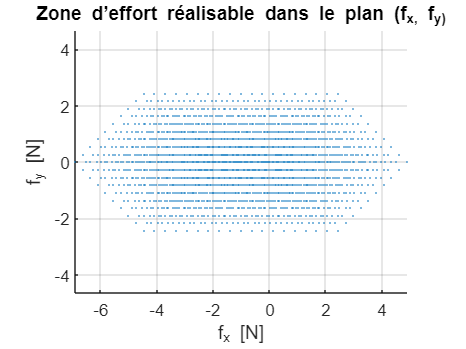


figure;
scatter(F(:,1), F(:,2), 1, 'filled');
xlabel('f_x [N]');
ylabel('f_y [N]');
title('Zone d’effort réalisable dans le plan (f_x, f_y)');
axis equal;
grid on;

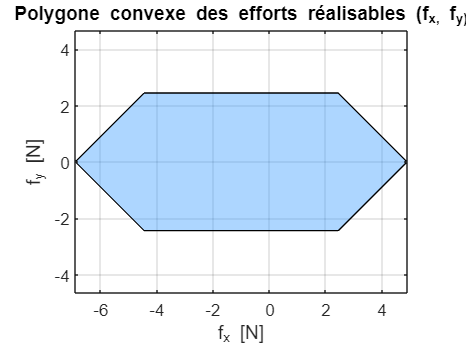

% Calcul de l'enveloppe convexe
K = convhull(F(:,1), F(:,2));

% Affichage
figure;
fill(F(K,1), F(K,2), [0.2 0.6 1], 'FaceAlpha', 0.4);
xlabel('f_x [N]'); ylabel('f_y [N]');
title('Polygone convexe des efforts réalisables (f_x, f_y)');
axis equal; grid on;

% Calcul de l'alphashape
shp = alphaShape(F(:,1), F(:,2), 0.05);

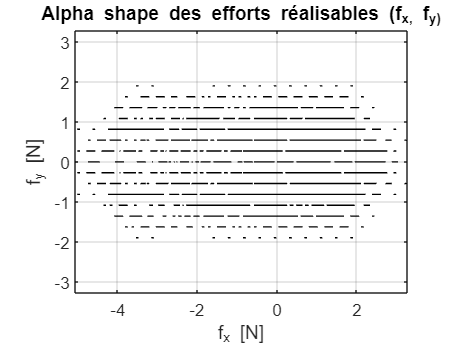


% Affichage
figure;
plot(shp, 'FaceColor', [0.2 0.6 1], 'FaceAlpha', 0.4);
xlabel('f_x [N]');
ylabel('f_y [N]');
title('Alpha shape des efforts réalisables (f_x, f_y)');
axis equal; grid on;

#### Calcul des efforts réalisables à couple nul

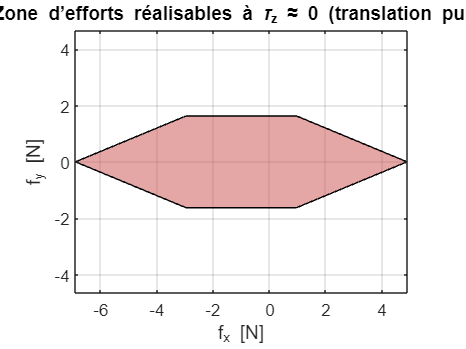

n = 10;
motor_forces = combvec( ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n), ...
    linspace(f_min, f_max, n))';
F_big = (W * motor_forces')';


% Seuil de tolérance sur le couple
tauz_tol = 1e-2;

% Garder uniquement les cas où tauz ≈ 0
F_zero_tauz = F_big(abs(F(:,3)) < tauz_tol, :);

% Enveloppe convexe de ces points
K_zero = convhull(F_zero_tauz(:,1), F_zero_tauz(:,2));

% Affichage
figure;
fill(F_zero_tauz(K_zero,1), F_zero_tauz(K_zero,2), [0.8 0.3 0.3], 'FaceAlpha', 0.5);
xlabel('f_x [N]'); ylabel('f_y [N]');
title('Zone d’efforts réalisables à \tau_z ≈ 0 (translation pure)');
axis equal; grid on;

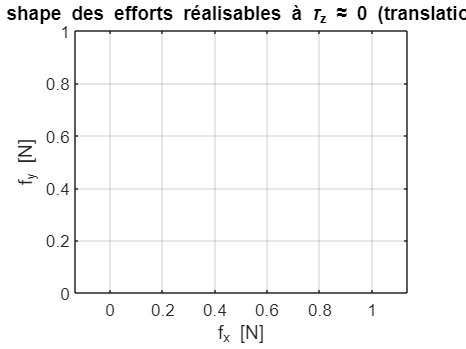

shp_zero = alphaShape(F_zero_tauz(:,1), F_zero_tauz(:,2), 0.03);
figure;
plot(shp_zero, 'FaceColor', [0.8 0.3 0.3], 'FaceAlpha', 0.5);
xlabel('f_x [N]');
ylabel('f_y [N]');
title('Alpha shape des efforts réalisables à \tau_z ≈ 0 (translation pure)');
axis equal; grid on;

#### Calcul des efforts réalisables

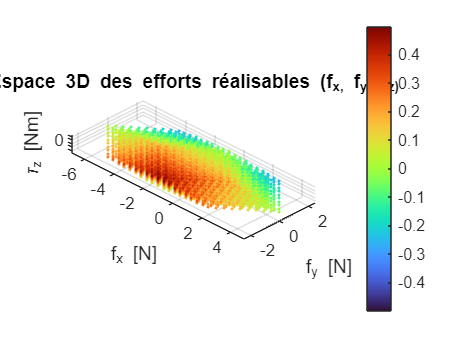

figure;
scatter3(F(:,1), F(:,2), F(:,3), 3, F(:,3), 'filled');
xlabel('f_x [N]'); ylabel('f_y [N]'); zlabel('\tau_z [Nm]');
title('Espace 3D des efforts réalisables (f_x, f_y, \tau_z)');
axis equal; grid on; view(45, 30);
colorbar; colormap turbo;